%leonard3_only_lenght_measured_peaks.mlx

clc;
clear;

% Beam Details
Bb = 50e-3;    % Width of the Beam (m)
d = 2700;      % Density of Beam Material (kg/m^3) for Aluminum
E = 70e9;      % Modulus of Elasticity of Beam Material (Pa) for Aluminum
Mt = 0.005;    % Tip Mass (kg)

L_values = linspace(0.2, 1, 10);  % Length values to iterate over
Db_values = linspace(2e-3, 2e-3, 1);  % Depth values to iterate over
fn_values = zeros(4, length(L_values), length(Db_values));  % 3D Matrix to store fn values

% Predefine the symbolic variables and equations
syms bL_sym
C = cos(bL_sym);
S = sin(bL_sym);
Ch = cosh(bL_sym);
Sh = sinh(bL_sym);
A1 = (S + Sh) / (C + Ch);
eqn_template = @(m, Mt, L) m * (-cos(bL_sym) - cosh(bL_sym) - A1 * (sin(bL_sym) - sinh(bL_sym))) + ...
                          Mt * (bL_sym / L) * (sin(bL_sym) - sinh(bL_sym) - A1 * (cos(bL_sym) - cosh(bL_sym))) == 0;

% Precompute the lengths in cm
L_values_cm = L_values * 100;

% Define different line styles for each depth
line_styles = {'-', '--', ':', '-.', '--'};

for k = 1:length(Db_values)
    Db = Db_values(k);
    for j = 1:length(L_values)
        L = L_values(j);
        Mb = (L * Bb * Db) * d;                % Mass of Beam (kg)
        I = Bb * Db^3 / 12;     
        m = Mb / L;                            % Mass per unit length of Beam (kg/m)

        eqn = eqn_template(m, Mt, L);  % Use the precomputed equation template

        % Find the first 4 solutions within a suitable range
        bLi = [];
        search_start = 1;  % Start point for vpasolve search range
        search_end = 2;    % End point for vpasolve search range
        while length(bLi) < 4 && search_end <= 30
            bL_sol = vpasolve(eqn, bL_sym, [search_start, search_end]);
            bL_sol = double(bL_sol);
            bLi = [bLi, bL_sol.'];
            search_start = search_end;
            search_end = search_end + 1;
        end
        if length(bLi) < 4
            warning('Not enough solutions found for L=%.2f and Db=%.2f', L, Db);
            continue; % Skip this iteration if not enough solutions are found
        end
        bLi = bLi(1:4);  % Take the first 4 solutions

        wn = bLi.^2 * sqrt((E * I) / (m * L^4));
        fn = wn / (2 * pi); % in Hz

        fn_values(:, j, k) = fn;  % Store the fn values for current L and Db
    end
end

% Read points from spreadsheet
spreadsheet_file = 'points_data.xlsx';  % Replace with your actual file path
data = readtable(spreadsheet_file);

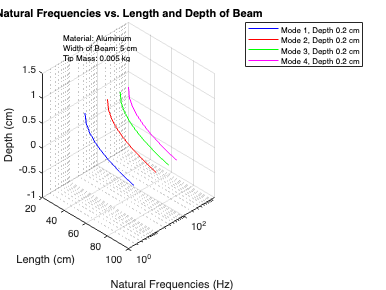


% Plotting the 3D graph
figure;
hold on;
colors = ['b', 'r', 'g', 'm'];
for i = 1:4
    for k = 1:length(Db_values)
        if all(fn_values(i, :, k) == 0)
            continue; % Skip if no valid data for this combination
        end
        plot3(L_values_cm, fn_values(i, :, k), Db_values(k) * 100 * ones(size(L_values_cm)), ...
              'Color', colors(i), 'LineStyle', line_styles{k}, 'DisplayName', ['Mode ' num2str(i) ', Depth ' num2str(Db_values(k)*100) ' cm']);
    end
end
xlabel('Length (cm)');
ylabel('Natural Frequencies (Hz)');
zlabel('Depth (cm)');
title('Natural Frequencies vs. Length and Depth of Beam');
set(gca, 'YScale', 'log');
grid on;
hold off;

% Set 3D view angle
view(45, 30);

% Adding smaller annotations at original location
dim = [.15 .6 .3 .3];
str = {'Material: Aluminum', ['Width of Beam: ', num2str(Bb*100), ' cm'], ['Tip Mass: ', num2str(Mt), ' kg']};
annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on', 'FontSize', 8, 'EdgeColor', 'none');

% Add a smaller legend outside the plot area
legend('Location', 'northeastoutside', 'FontSize', 8);

% Save the 3D figure
output_folder = 'output_figures'; % Specify your desired folder
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end
output_filename = sprintf('3D_Plot_TipMass_%.1fkg_Material_Aluminum_Width_%.2fcm', Mt, Bb*100);
saveas(gcf, fullfile(output_folder, [output_filename, '.png']));

savefig(fullfile(output_folder, [output_filename, '.fig']));

disp('3D Figure saved successfully.');

3D Figure saved successfully.


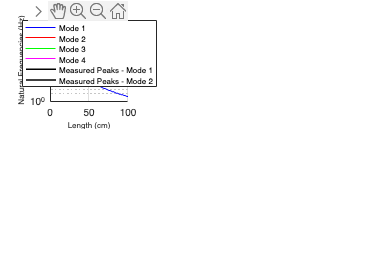


% Create a figure to hold all 5 2D plots
combined_fig = figure;
set(combined_fig, 'Position', [100, 100, 1200, 800]);  % Set the size of the figure

for k = 1:length(Db_values)
    subplot(2, 3, k);
    hold on;
    for i = 1:4
        if all(fn_values(i, :, k) == 0)
            continue; % Skip if no valid data for this combination
        end
        plot(L_values_cm, squeeze(fn_values(i, :, k)), 'Color', colors(i), 'LineStyle', line_styles{k}, 'DisplayName', ['Mode ' num2str(i)]);
    end
    
    % Plot the points from the spreadsheet separately for each mode
    unique_modes = unique(data.Mode);
    for mode = unique_modes'
        mode_data = data(data.Mode == mode, :);
        plot(mode_data.Length, mode_data.Frequency, 'k-', 'LineWidth', 1.5, 'DisplayName', ['Measured Peaks - Mode ' num2str(mode)]);
    end
    
    xlabel('Length (cm)', 'FontSize', 8);
    ylabel('Natural Frequencies (Hz)', 'FontSize', 8);
    title(['Depth ' num2str(Db_values(k) * 100) ' cm'], 'FontSize', 10);
    set(gca, 'YScale', 'log');
    grid on;
    legend('show', 'FontSize', 8, 'Location', 'best');
    hold off;
end

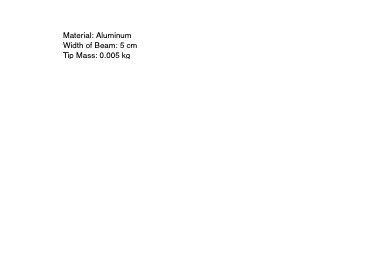


% Adjust the layout of subplots
subplot(1,1,1);
axis off;
dim = [.15 .6 .3 .3];  % Adjusted position for better visibility
str = {'Material: Aluminum', ['Width of Beam: ', num2str(Bb*100), ' cm'], ['Tip Mass: ', num2str(Mt), ' kg']};
annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on', 'FontSize', 8, 'EdgeColor', 'none');

% Save the combined figure with higher resolution
combined_output_filename = sprintf('Combined_2D_Plots_TipMass_%.1fkg_Material_Aluminum_Width_%.2fcm', Mt, Bb*100);
print(combined_fig, fullfile(output_folder, [combined_output_filename, '.png']), '-dpng', '-r300');  % Save at 300 DPI

savefig(combined_fig, fullfile(output_folder, [combined_output_filename, '.fig']));

disp('Combined Figure saved successfully.');

Combined Figure saved successfully.
